Retrieve Audio Sources

%Attain audio
[matthew, fs_m] = audioread("matthew_speak.mp3");
[kimberly, fs_k] = audioread("kimberly_speak.mp3");
[joey, fs_j] = audioread("joey_speak.mp3");
[ivy, fs_i] = audioread("ivy_speak.mp3");

Compare STFT, Mel Spectrogram, and MFCC

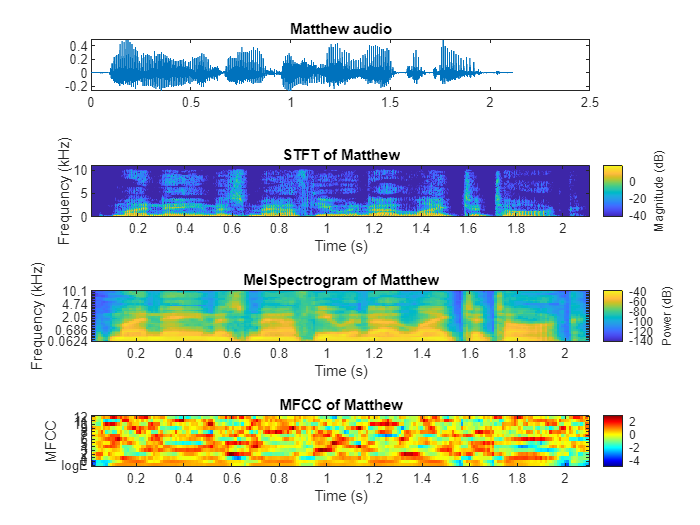

% Compare regular stft with mel spectrogram -- use matthew as example
%sound(matthew,fs_m);
t_m = (0:numel(matthew)-1)/fs_m;
figure;
tiledlayout(4,1)

%Signal
nexttile
plot(t_m, matthew);
title("Matthew audio")

%STFT
windowLength = 128;
fftLength = 128;
overlapLength = 96;
win = hann(windowLength,"periodic");
nexttile
matthew_stft = stft(matthew,fs_m,Window=win,OverlapLength=overlapLength,FFTLength=fftLength,FrequencyRange="onesided");
stft(matthew,fs_m,Window=win,OverlapLength=overlapLength,FFTLength=fftLength,FrequencyRange="onesided");
title("STFT of Matthew")

%melSpectrogram
nexttile
melSpectrogram(matthew,fs_m);
title("MelSpectrogram of Matthew")

%MFCCs
nexttile
mfcc(matthew,fs_m);
title("MFCC of Matthew")

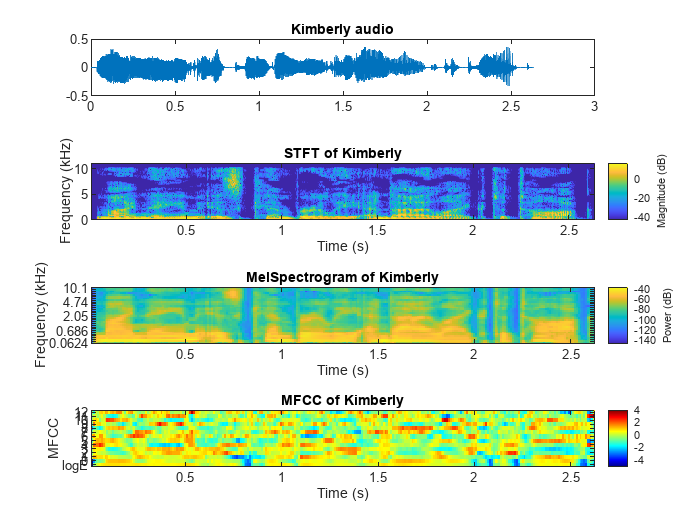

% Compare regular stft with mel spectrogram -- use kimberly
%sound(kimberly,fs_k);
t_k = (0:numel(kimberly)-1)/fs_k;
figure;
tiledlayout(4,1)

%Signal
nexttile
plot(t_k, kimberly);
title("Kimberly audio")

%STFT
windowLength = 128;
fftLength = 128;
overlapLength = 96;
win = hann(windowLength,"periodic");
nexttile
stft(kimberly,fs_k,Window=win,OverlapLength=overlapLength,FFTLength=fftLength,FrequencyRange="onesided");
title("STFT of Kimberly")

%melSpectrogram
nexttile
melSpectrogram(kimberly,fs_k);
title("MelSpectrogram of Kimberly")

%MFCCs
nexttile
mfcc(kimberly,fs_k);
title("MFCC of Kimberly")

Plot each coefficient and compare

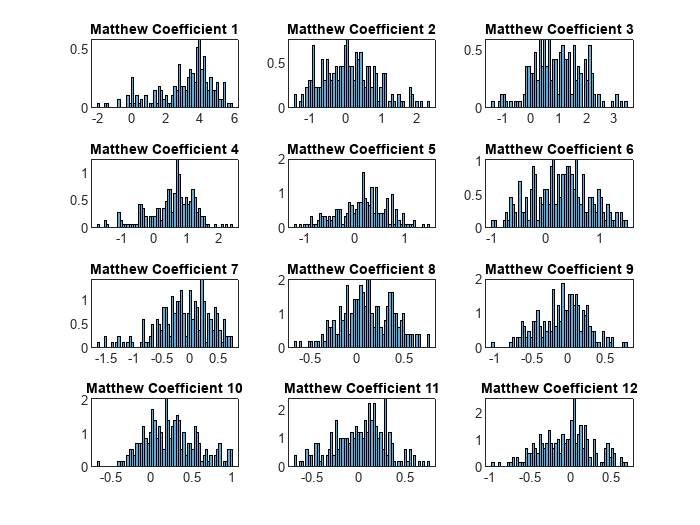

%Matthew
mat_co = mfcc(matthew,fs_m,"LogEnergy","Ignore");

%Kimberly
kim_co = mfcc(kimberly,fs_k,"LogEnergy","Ignore");

nbins = 60;
figure;
for i = 1:12
    nexttile
    histogram(mat_co(:,i+1),nbins,"Normalization","pdf");
    title(sprintf("Matthew Coefficient %d",i));
end

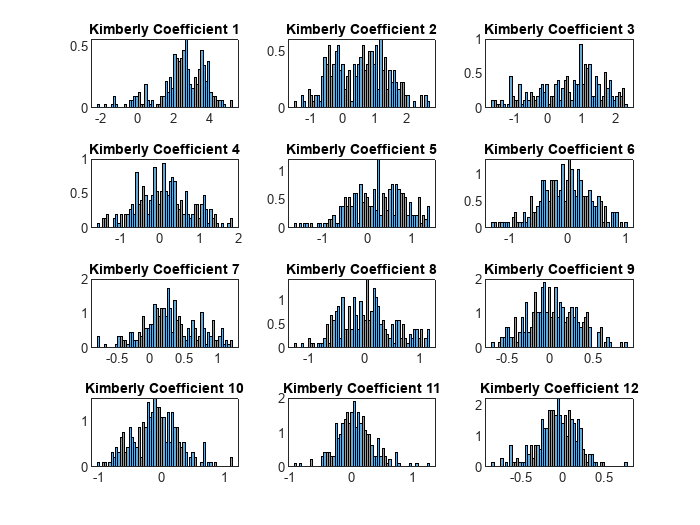

figure;
for i = 1:12   
    nexttile
    histogram(kim_co(:,i+1),nbins,"Normalization","pdf");
    title(sprintf("Kimberly Coefficient %d",i));
end

What are some coefficients with noticeable differences?

figure;
i = 12

i = 12

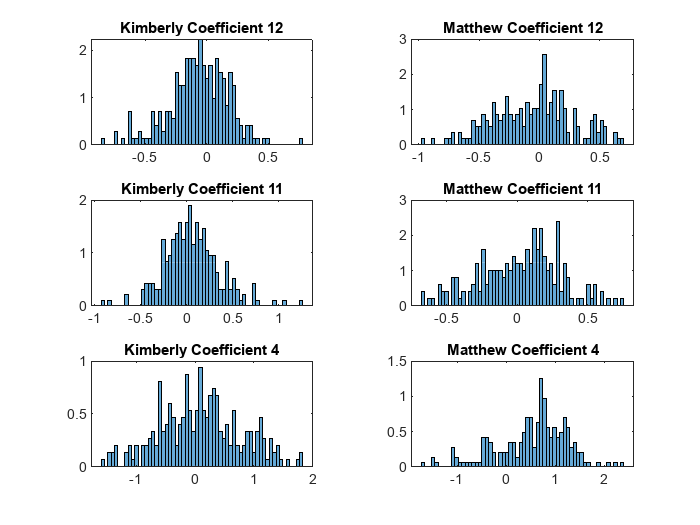

nexttile
histogram(kim_co(:,i+1),nbins,"Normalization","pdf");
title(sprintf("Kimberly Coefficient %d",i));

nexttile
histogram(mat_co(:,i+1),nbins,"Normalization","pdf");
title(sprintf("Matthew Coefficient %d",i));

i = 11;
nexttile
histogram(kim_co(:,i+1),nbins,"Normalization","pdf");
title(sprintf("Kimberly Coefficient %d",i));

nexttile
histogram(mat_co(:,i+1),nbins,"Normalization","pdf");
title(sprintf("Matthew Coefficient %d",i));

i = 4;
nexttile
histogram(kim_co(:,i+1),nbins,"Normalization","pdf");
title(sprintf("Kimberly Coefficient %d",i));

nexttile
histogram(mat_co(:,i+1),nbins,"Normalization","pdf");
title(sprintf("Matthew Coefficient %d",i));